clc
clear all
close all

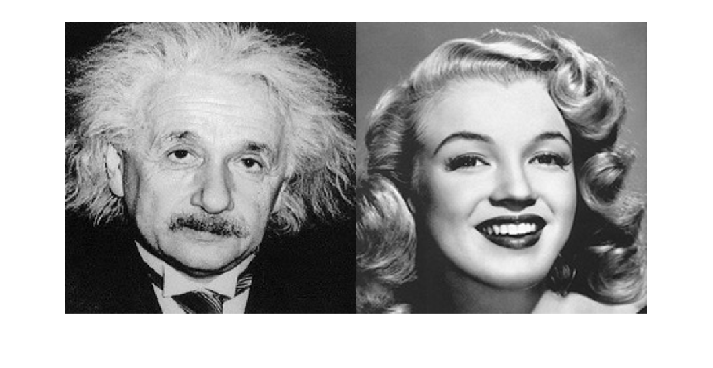

% Read in images
Marilynl = imread('marilyn.jpg');
Einsteinl = imread('einstein.jpg');

% convert to gray picture
Einsteinl = rgb2gray(Einsteinl);
% Marilynl = rgb2gray(Marilynl);  Marilynl is gray

% Resize images to be of same size
Resize = 512;
Marilynl = imresize(Marilynl, [Resize Resize]);
Einsteinl = imresize(Einsteinl, [Resize Resize]);

% Convert images to double precision
Marilyn  = double(Marilynl) ;
Einstein = double(Einsteinl);

% Set filter size
filter_size = 64;
% Define the standard deviation of the Gaussian filter
sigma = 8;
% Create the low-pass Gaussian filter
h = fspecial('gaussian', filter_size, sigma);
% Apply the low-pass filter to the image
low_pass_filtered_image = imfilter(Marilyn, h);

% Create the high-pass filter by subtracting the low-pass filter from an all-pass filter
filter_size = 250;
sigma = 0.05;
h = fspecial('gaussian', filter_size, sigma);
h_high = fspecial('average', filter_size) - h;
% Apply the high-pass filter to the image
high_pass_filtered_image = imfilter(Einstein, h_high);
% Display original images side-by-side in a montage
montage({Einsteinl,Marilynl})

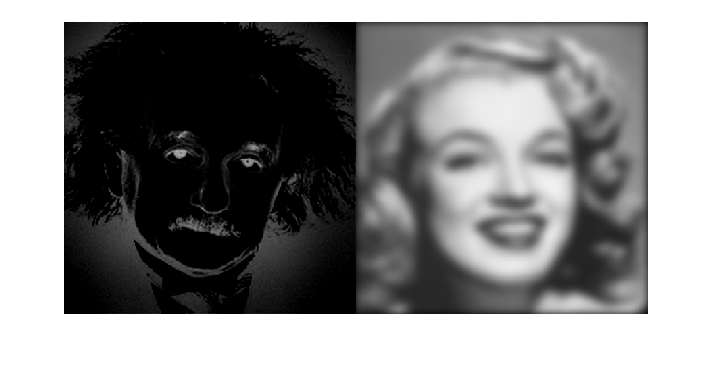

% Display filtered images side-by-side in a montage
montage({uint8(high_pass_filtered_image),uint8(low_pass_filtered_image)})

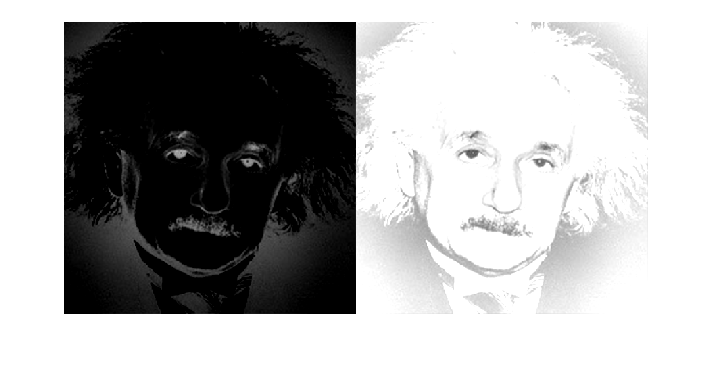

% Invert the high-pass_filtered_image color
white_high_pass_filtered_image = 255-high_pass_filtered_image;
% Display inverted and non-inverted high-pass filtered images side-by-side in a montage
montage({uint8(high_pass_filtered_image),uint8(white_high_pass_filtered_image)})

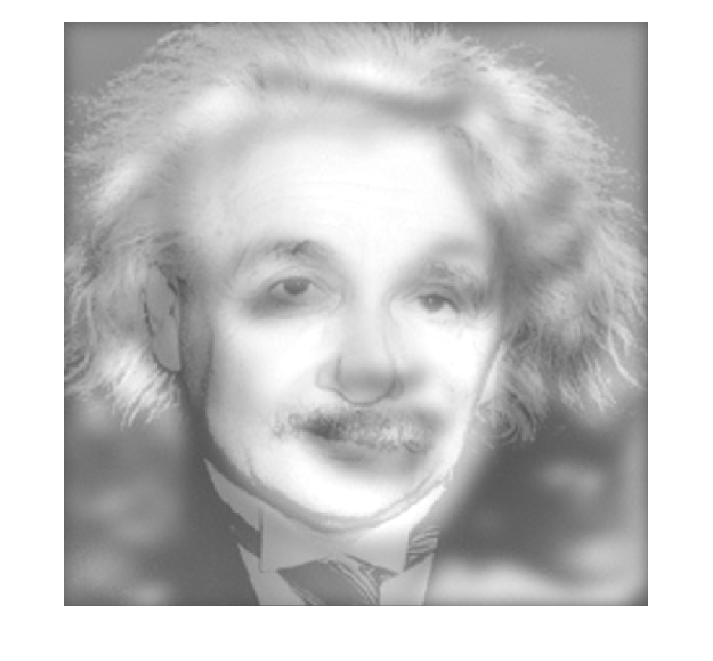

% Combine the inverted high-pass filtered image and the low-pass filtered image using weighted average
combined_image = 0.32*((white_high_pass_filtered_image)) + 0.68*((low_pass_filtered_image));
% Display combined image
montage({uint8(combined_image)})